# **Main Case  (Heterogeneous WITH NICHE INFORMATION)**

(Daniel Rojas, Sebastian Mejia, Jhon Smith, Andres Felipe)

% Parameters: mu_h, mu_m, gamma, z, beta_hm, beta_mh, r, C, v_h, v_m
pars = [0.0947, 0.5035,0.9635,9.1432,0.0826,0.9721,0.3684,1.982e3,1.5070,0.0242];
% Temporal Domain
domain = [1, 50];  % From t=1 to t=100
% Set Initial conditions
initial_conditions = [80, 20, 800, 200, 0]; 
names = {'M_S','M_I','H_s','H_I','H_R','\mu_h','\mu_m','\gamma','z','\beta_{hm}','\beta_{mh}','r','c_m','\nu_h','\nu_m'}; % Factors names
out_names = {'S_m()','I_m(t)','S_h(t)','I_h(t)','R_h(t)','Cumulative human infection cases','Mosquitoes Population','Human Population'}; % Output Names
factors = [initial_conditions,pars];
% Ranges
rpars = [0 0.6;0 1;0.1 1; 0 30;0 1;0 1;0 100;0 2e3;0 1e2;0 1e2];
rconds = [80 80; 0 70; 800 800; 0 300; 0 0];
range = [rconds;rpars];
% Gsua Toolbox implementation
TU = gsua_dataprep('SIR1',range,'domain',domain,'out_names',out_names,'names',names);

Setting environment to work with user-defined function


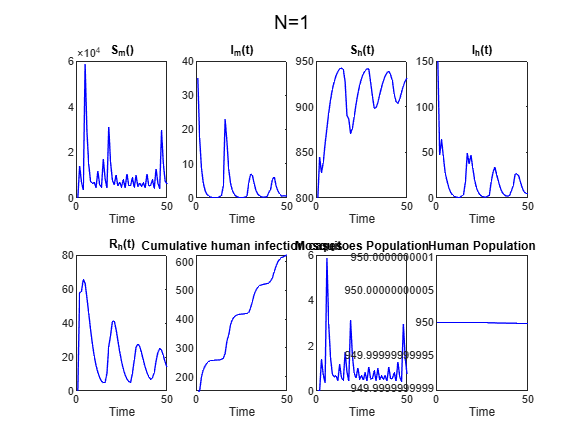

y=gsua_eval(TU.Nominal,TU);

TU.Properties.CustomProperties.output =6;

# **Import data**

Below, we present the main case, which includes the parameter values for the agent-based simulation.

The parameters marked with * correspond to simulator values that can be scaled to weeks, while the other parameters are not scalable.

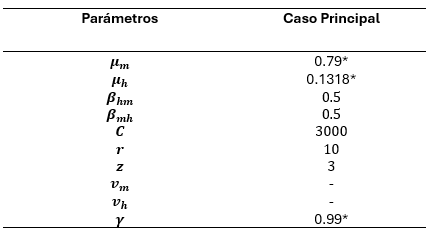

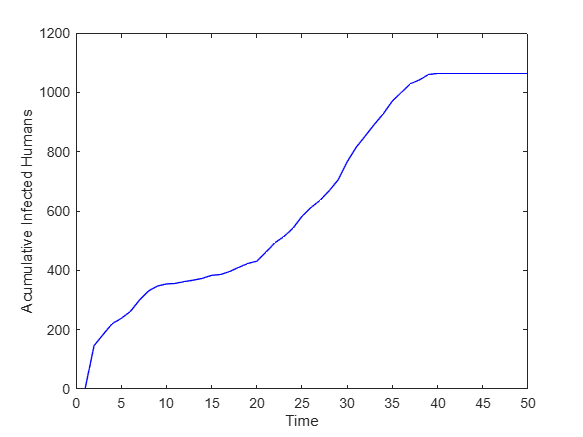

load NoUniforme2_2.mat
close all

%Figure data Acumulative Infected Humans
xdata1=1:50;
dataY1=Hi_No_uniforme(xdata1);
plot(dataY1,color='blue');
xlabel('Time');
ylabel('Acumulative Infected Humans');

M=gsua_dmatrix(TU,20000); %Set of parameters of TU samples
TU

TU = 12x2 table
                     Range       Nominal
                  ___________    _______

    M_I             0      70       35  
    H_I             0     300      150  
    \mu_h           0     0.6      0.3  
    \mu_m           0       1      0.5  
    \gamma        0.1       1     0.55  
    z               0      30       15  
    \beta_{hm}      0       1      0.5  
    \beta_{mh}      0       1      0.5  
    r               0     100       50  
    c_m             0    2000     1000  
    \nu_h           0     100       50  
    \nu_m           0     100       50  


# **Sensitivity analysis**

[TU,J,Y]=gsua_sa(M,TU,'SensMethod','Xiao');

Progress: 8%
Estimated processing time (h:m:s): 0:0:45
Remaining time (h:m:s): 0:0:42
Elapsed time (h:m:s): 0:0:3
Estimated stop time (h:m:s): 23:37:4
Number of simulations: 140000
Progress: 15%
Estimated processing time (h:m:s): 0:0:33
Remaining time (h:m:s): 0:0:28
Elapsed time (h:m:s): 0:0:4
Estimated stop time (h:m:s): 23:36:52
Number of simulations: 140000
Progress: 22%
Estimated processing time (h:m:s): 0:0:29
Remaining time (h:m:s): 0:0:23
Elapsed time (h:m:s): 0:0:6
Estimated stop time (h:m:s): 23:36:48
Number of simulations: 140000
Progress: 29%
Estimated processing time (h:m:s): 0:0:28
Remaining time (h:m:s): 0:0:20
Elapsed time (h:m:s): 0:0:8
Estimated stop time (h:m:s): 23:36:47
Number of simulations: 140000
Progress: 36%
Estimated processing time (h:m:s): 0:0:28
Remaining time (h:m:s): 0:0:18
Elapsed time (h:m:s): 0:0:10
Estimated stop time (h:m:s): 23:36:47
Number of simulations: 140000
Progress: 43%
Estimated processing time (h:m:s): 0:0:27
Remaining time (h:m:s): 0:0:15

TU.Si;
sum(TU.Si);
sum(TU.Si)/sum(abs(TU.Si)) %Reliability index

ans = 0.8634

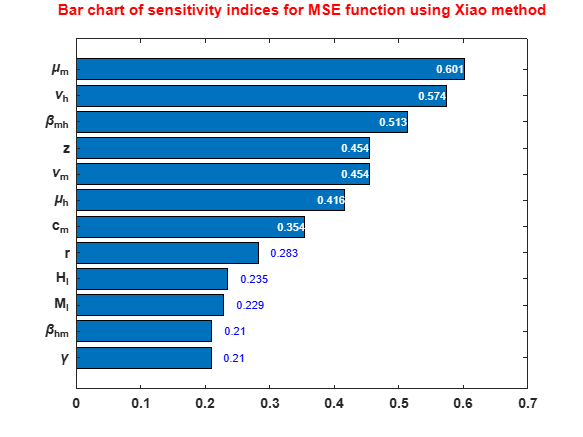

sum(TU.STi);
clf
gsua_plot('Bar',TU,TU.STi)
colormap jet

# **Uncertainty analysis**

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 16:19:55
Number of simulations: 1000


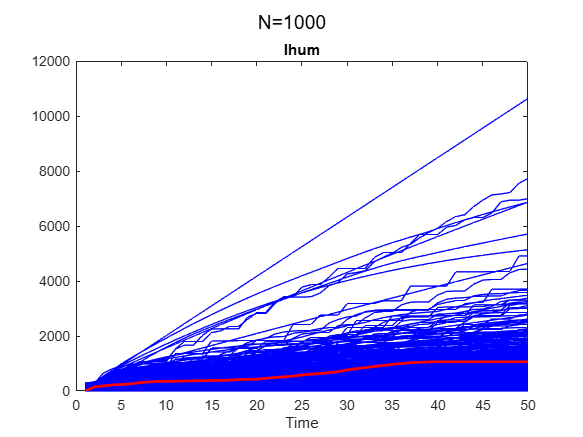

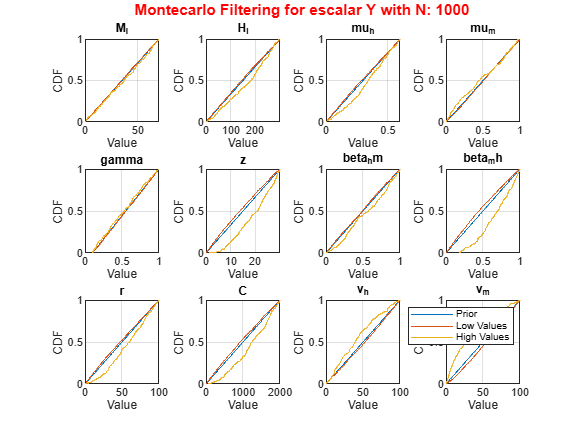

close all
gsua_ua(M,TU,'xdata',xdata1,'parallel',false,'ynom',dataY1);

# **Time series (Mathematical indicator of ecological niche)**

% Extraction of information from the maps
map1 = matrix_Map_No_Uni{1};%Information Home-Humans
map2 = matrix_Map_No_Uni{2}; %Information Work Humans
map3 = matrix_Map_No_Uni{3}; %Map Vector

H1 = map1(2:end, 3); %Map Home-Humans
H2 = map2(2:end, 3); %Map Work-Humans
V = map3(2:end, 3:end); %Map Vector

V =     0.0121    0.3016    0.1345    0.2081         0    0.2235    0.1061         0    0.0000    0.0000         0         0         0         0         0         0    0.5689    0.1445    0.3676    0.5824    0.5732    0.5771    0.6994    0.6193    0.6557    0.6652    0.6857    0.6741    0.0023    0.4890    0.2704    0.5413    0.1924    0.2787    0.5752    0.4602    0.4076    0.6313    0.5908    0.6092    0.7520    0.6749    0.7264    0.5058    0.6532    0.5702    0.2715    0.4190    0.3391    0.2555
    0.9098    0.9426    0.9244    0.9324    0.9860    0.9538    0.9707    0.9430    0.9729    0.9602    0.7106    0.8541    0.7940    0.9187    0.8108    0.8289    0.3338    0.7701    0.5407    0.4246    0.3626    0.3893    0.4429    0.4304    0.4361    0.4536    0.4472    0.4508    0.8950    0.5709    0.7165    0.6591    0.8118    0.7740    0.8713    0.7123    0.7924    0.9533    0.8943    0.9236    0.8369    0.9092    0.8731    0.8214    0.8314    0.8251    0.6472    0.7557    0.7100    0

result_matrix = zeros(1, size(V, 2));
H = max([H1,H2],[],2); %Function max Map Work-Home
H_ponderador = H/sum(H); %Normalization of H 

H_ponderador =          0
    0.0000
    0.0000
         0
    0.0002
    0.0003
    0.0000
    0.0001
    0.0004
    0.0003


V_ponderador = V./sum(V) %Normalization Vector

V_ponderador = 1.0e-03 *

    0.0060    0.1393    0.0654    0.0990         0    0.1043    0.0504         0    0.0000    0.0000         0         0         0         0         0         0    0.2619    0.0696    0.1742    0.2744    0.2663    0.2701    0.3170    0.2890    0.3029    0.2966    0.3095    0.3027    0.0012    0.2298    0.1337    0.3509    0.1119    0.1788    0.3118    0.2971    0.2453    0.2741    0.3035    0.2907    0.3419    0.3004    0.3273    0.2733    0.3186    0.2966    0.1667    0.2392    0.2014    0.1564
    0.4505    0.4354    0.4494    0.4436    0.4707    0.4449    0.4615    0.4755    0.4859    0.4879    0.4053    0.4550    0.4366    0.4425    0.4317    0.4243    0.1536    0.3710    0.2562    0.2001    0.1685    0.1822    0.2008    0.2009    0.2015    0.2022    0.2019    0.2024    0.4672    0.2682    0.3542    0.4272    0.4721    0.4966    0.4723    0.4599    0.4768    0.4138    0.4594    0.4407    0.3805    0.4047    0.3935    0.4438    0.4055    0.4291    0.3973   

nuH=sum(V.*H_ponderador) %Indicator for V_h(t)

nuH =     0.4655    0.4809    0.4705    0.4747    0.4552    0.4707    0.4615    0.4396    0.4438    0.4393    0.4390    0.4367    0.4374    0.4620    0.4467    0.4540    0.4615    0.4606    0.4605    0.4466    0.4559    0.4511    0.4555    0.4487    0.4510    0.4577    0.4551    0.4563    0.4078    0.4377    0.4235    0.1661    0.3145    0.2356    0.2103    0.1701    0.1891    0.2572    0.2189    0.2331    0.2297    0.2464    0.2383    0.2229    0.2260    0.2223    0.2095    0.2105    0.2065    0.2003


nuM=sum(H.*V_ponderador)  %Indicator for V_m(t)

nuM =     0.2142    0.2064    0.2125    0.2098    0.2019    0.2040    0.2039    0.2060    0.2059    0.2074    0.2327    0.2162    0.2235    0.2068    0.2210    0.2159    0.1974    0.2062    0.2027    0.1955    0.1968    0.1962    0.1919    0.1946    0.1936    0.1896    0.1909    0.1904    0.1978    0.1911    0.1945    0.1001    0.1700    0.1404    0.1059    0.1020    0.1057    0.1037    0.1045    0.1033    0.0970    0.1019    0.0998    0.1119    0.1024    0.1074    0.1195    0.1117    0.1140    0.1139


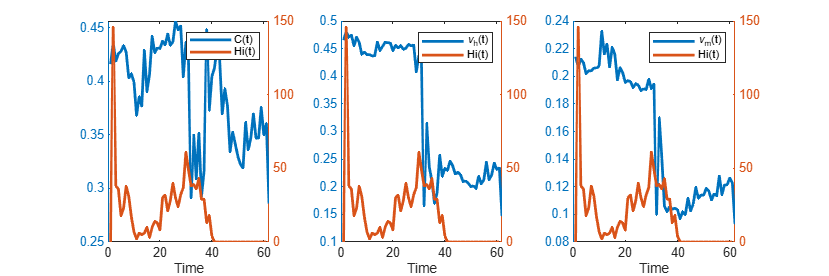

Ct=mean(V(H~=0,:));  %Indicator for Mosquito Carrying Capacity
Hi_noAcc=Hi_No_uniforme-[0,Hi_No_uniforme(1:end-1)]; %Cases per week of dengue

%Figure Indicator for Mosquito Carrying Capacity, Indicator for V_m(t), Indicator for V_h(t) vs.
% Cases per week for dengue
figure('Position',[10 10 1200 400])
clf
subplot(1,3,1)
yyaxis left
plot(Ct,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"C(t)","Hi(t)"})
xlabel('Time') 
subplot(1,3,2)
yyaxis left
plot(nuH,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"\nu_h(t)","Hi(t)"})
xlabel('Time') 
subplot(1,3,3)
yyaxis left
plot(nuM,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"\nu_m(t)","Hi(t)"})
xlabel('Time') 

# **Link the time series to the model**

Prepare the structure to input the time series into the model

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 16:20:13
Number of simulations: 1000


dataIn=struct();
dataIn.timeSer=Ct;
dataIn.Nuh=nuH;
dataIn.Num=nuM;
dataIn.action=2;

TU.Properties.CustomProperties.copt=dataIn;%The time series is assigned to the model
close all
gsua_ua(M,TU,'xdata',xdata1,'parallel',false,'ynom',dataY1);%Uncertainty analysis

# **Parameter estimation**

solver='fmincon';%this is the default solver
opt=optimoptions('fmincon','UseParallel',false,'MaxIterations',5e4,'MaxFunctionEvaluations',1e5);%configure optimizer
nestim=1000;
resT=zeros(1,nestim);
IPT=zeros(size(TU,1),nestim);
estimations=zeros(size(TU,1),nestim);

parfor i=1:nestim
    [T_e,res,IP] =gsua_pe(TU,xdata1,dataY1,'N',1,'solver',solver,'Show','off','opt',opt,'margin',0.3);
    IPT(:,i)=IP;
    resT(i)=res;
    estimations(:,i)=T_e.Estfmincon;
    clc
    if mod(i,30)==0
        disp("Progress "+num2str(round(nestim/i*100)))
    end
end

Generating a valid matrix for estimations
Estimation 1

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Progress: 100%
Estimated processing time (h:m:s): 0:0:22
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:22
Estima


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 18:31:1
Number of simulations: 1
Generating a valid matrix for estimations
Es


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 1.000000e+05.

Progress: 100%
Estimated processing time (h:m:s): 0:1:16
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:1:16
Estimated stop time (h:m:s): 19:26:16
Number of simulations: 1
Generating a valid matrix for estimations
Estimation 1

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the

%[T_e,res,IP] =gsua_pe(TU,xdata1,dataY1,'N',nestim,'solver',solver,'Show','on','opt',opt,'margin',0.3);
[sortedResT,idx]=sort(resT,'ascend');
sortedEstims=estimations(:,idx);
IPT=IPT(:,idx);

save("ALEPHCambio2ResultsEstims1000NU2_SA.mat","sortedResT","sortedEstims","IPT");%SA stands for serie activa

# **Identifiability analysis**

clear;clc;close all
% Parameters: mu_h, mu_m, gamma, z, beta_hm, beta_mh, r, C, v_h, v_m
pars = [0.00145, 0.3848,0.9776,5.9052,0.9628,0.8030,13.9406,0.0182,4.78e3,1.58e4];
% Temporal Domain
domain = [1, 50];  % From t=1 to t=100
% Set Initial conditions
initial_conditions = [80, 20, 800, 200, 0]; 
names = {'M_S','M_I','H_s','H_I','H_R','\mu_h','\mu_m','\gamma','z','\beta_{hm}','\beta_{mh}','r','c_m','\nu_h','\nu_m'}; % Factors names
out_names = {'S_m()','I_m(t)','S_h(t)','I_h(t)','R_h(t)','heterogeneous scenario with niche information','Mosquitoes','Human'}; % Output Names
factors = [initial_conditions,pars];
% Ranges
rpars = [0 0.6;0 1;0.1 1; 0 30;0 1;0 1;0 100;0 2e3;0 1e2;0 1e2];
rconds = [80 80; 0 70; 800 800; 0 300; 0 0];
range = [rconds;rpars];
% Gsua Toolbox implementation
TU = gsua_dataprep('SIR1',range,'domain',domain,'out_names',out_names,'names',names);

Setting environment to work with user-defined function


%File with parameter estimation and data information
load ALEPHCambio2ResultsEstims1000NU2_SA
load NoUniforme2_2.mat

% Times series
map1 = matrix_Map_No_Uni{1};
map2 = matrix_Map_No_Uni{2};
map3 = matrix_Map_No_Uni{3};

H1 = map1(2:end, 3);
H2 = map2(2:end, 3);
V = map3(2:end, 3:end);
result_matrix = zeros(1, size(V, 2));
H = max([H1,H2],[],2);
H_ponderador = H/sum(H);
V_ponderador = V./sum(V);
V.*H_ponderador;
nuH=sum(V.*H_ponderador); %Indicator for V_h(t)
H.*V_ponderador;
nuM=sum(H.*V_ponderador); %Indicator for V_m(t)
Ct=mean(V(H~=0,:)) %Indicator for Mosquito Carrying Capacity

Ct =     0.4160    0.4358    0.4187    0.4256    0.4280    0.4333    0.4272    0.4030    0.4071    0.3994    0.3681    0.3856    0.3767    0.4289    0.3905    0.4066    0.4419    0.4266    0.4311    0.4306    0.4375    0.4339    0.4442    0.4335    0.4369    0.4562    0.4478    0.4517    0.4041    0.4361    0.4195    0.2912    0.3499    0.3089    0.3518    0.2926    0.3164    0.4482    0.3730    0.4044    0.4125    0.4308    0.4202    0.3695    0.3931    0.3773    0.3341    0.3525    0.3417    0.3300


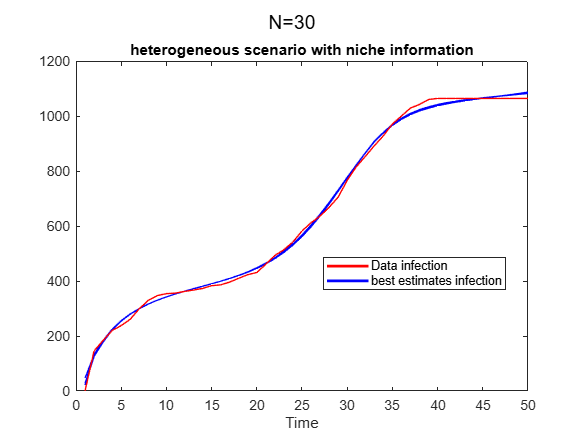

Hi_noAcc=Hi_No_uniforme-[0,Hi_No_uniforme(1:end-1)]; %Cases per week of dengue
figure('Position',[10 10 1200 400])
clf
subplot(1,3,1)
yyaxis left
plot(Ct,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"C(t)","Hi(t)"})
subplot(1,3,2)
yyaxis left
plot(nuH,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"\nu_h(t)","Hi(t)"})
subplot(1,3,3)
yyaxis left
plot(nuM,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"\nu_m(t)","Hi(t)"})

dataIn=struct();
dataIn.timeSer=Ct;
dataIn.Nuh=nuH;
dataIn.Num=nuM;
dataIn.action=2;

TU.Properties.CustomProperties.copt=dataIn;%The time series is assigned to the model
TU.Properties.CustomProperties.output = 6;

xdata1=1:50;
dataY1=Hi_No_uniforme(xdata1);
dataY2=Hi_noAcc(xdata1);
thr=min(sortedResT)*2; %Solution acceptance criterion
TU.Estims=sortedEstims;
close all
selector=sum(sortedResT<thr);  %Selection of the best estimates

figure(1)
y1=gsua_eval(TU.Estims(:,1:selector), TU, xdata1, dataY1); 

hold on
h1 = plot(NaN, NaN, 'r', 'LineWidth', 2); % Línea roja para 'data'
h2 = plot(NaN, NaN, 'b', 'LineWidth', 2); % Línea azul para 'best estimates'
hold off

legend([h1, h2], 'Data infection', 'best estimates infection', 'Location', 'best');

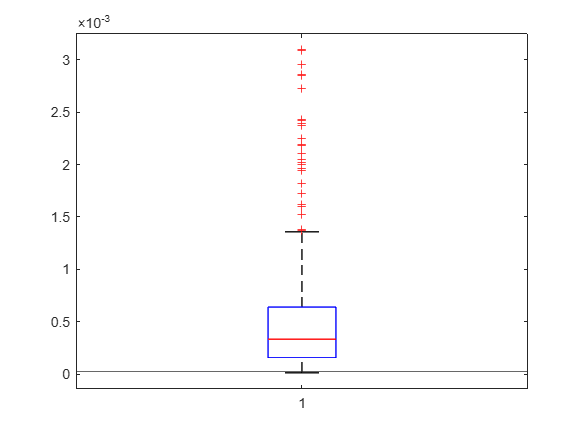

figure(2)
clf
boxplot(sortedResT(1:200))
hold on
yline(thr)

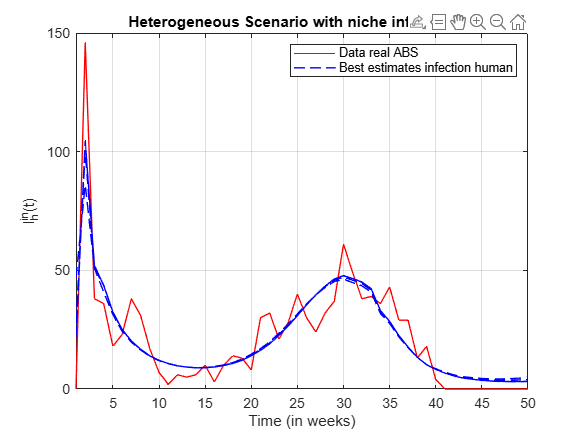

Hi=Hi_No_uniforme-[0 Hi_No_uniforme(1:end-1)];
close all, figure(2), plot(Hi,Color="r")
hold on
y=y1-[zeros(30,1) y1(:,1:end-1)];
plot(y','--',LineWidth=1,color="b");
grid on;

legend('Data real ABS','Best estimates infection human')
title("Heterogeneous Scenario with niche information")
xlabel("Time (in weeks)")
ylabel("I_{h}^{in}(t)")
xlim([1 50])

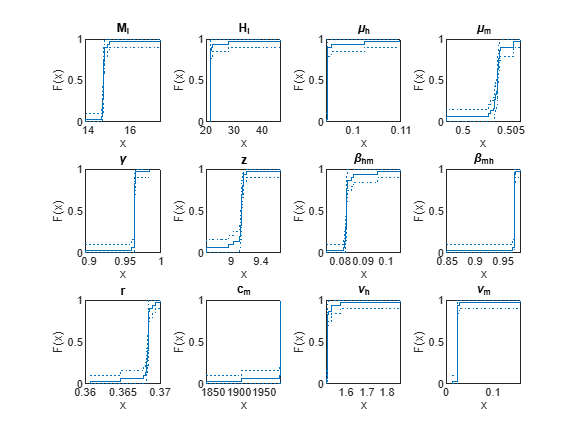

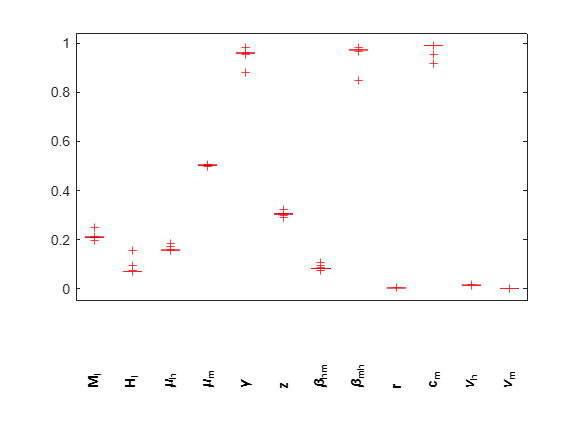

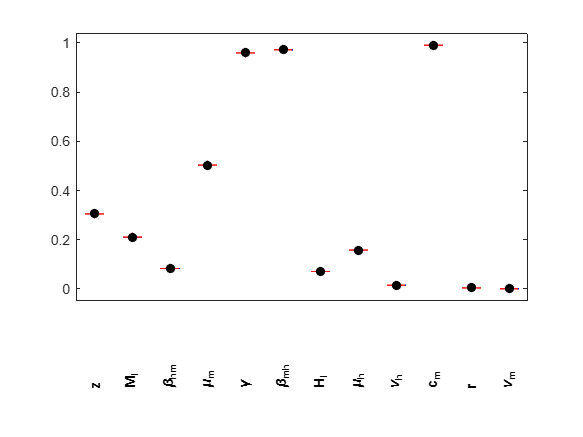

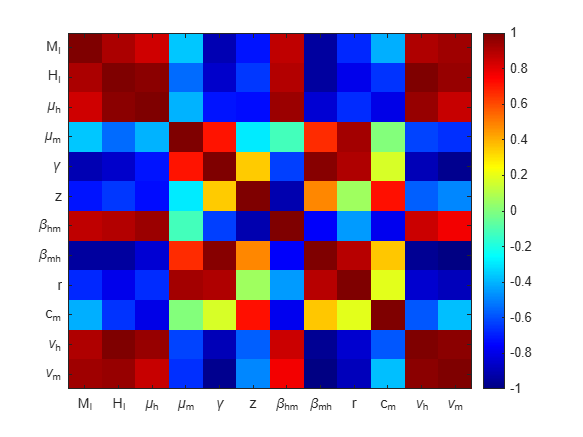

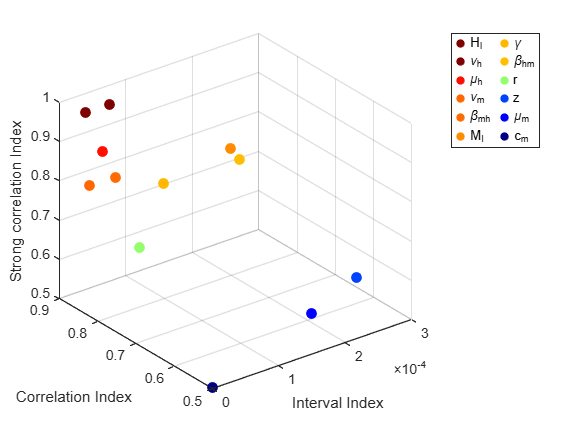

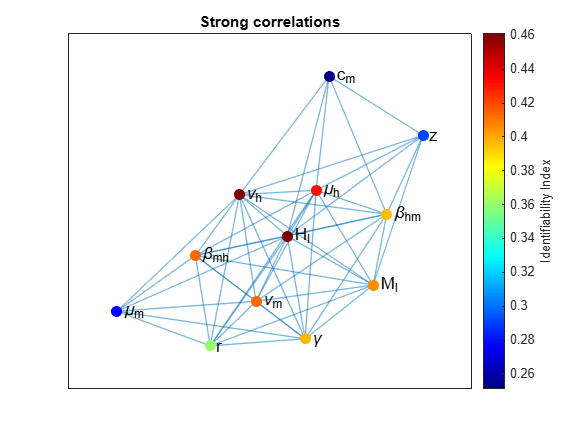

T = 12x5 table
                         Range            Nominal        Estims            Est         index 
                  ____________________    ________    _____________    ___________    _______

    M_I             14.734      14.748      14.744    1x1000 double    1x30 double    0.40569
    H_I             21.527       21.54      21.534    1x1000 double    1x30 double    0.46145
    \mu_h         0.094697    0.094704    0.094702    1x1000 double    1x30 double    0.43186
    \mu_m          0.50348     0.50364     0.50357    1x1000 double    1x30 double    0.27681
    \gamma         0.96349     0.96355     0.96352    1x1000 double    1x30 double    0.39721
    z               9.1347      9.1426      9.1373    

close all
Tia=gsua_ia(TU,TU.Estims(:,1:selector),true,false,true); %Identifiability analysis

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 9:37:17
Number of simulations: 1000


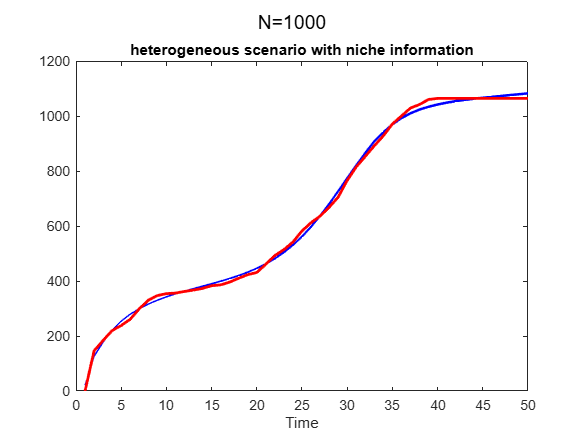

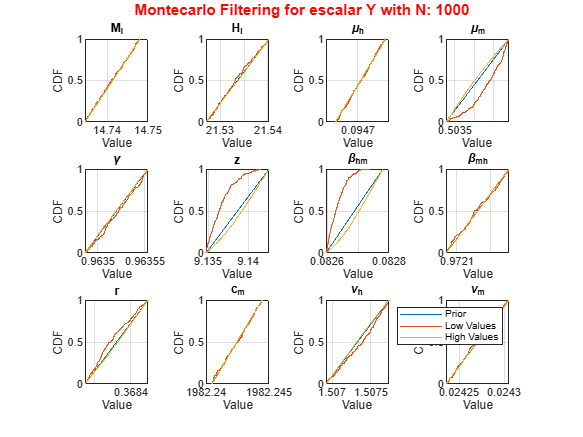

close all
Mia=gsua_dmatrix(Tia,1e3);
gsua_ua(Mia,TU,'xdata',xdata1,'parallel',false,'ynom',dataY1);

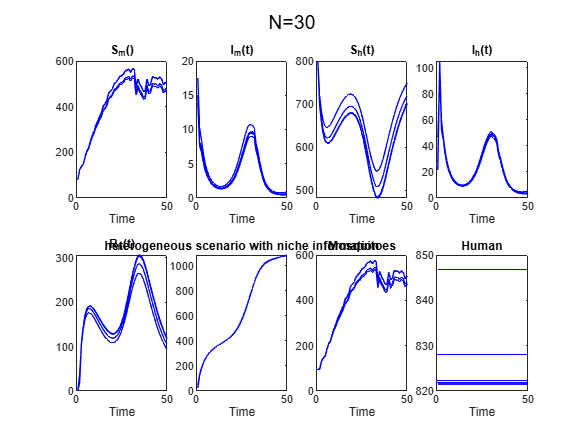

close all
TU.Properties.CustomProperties.output=1:8;
gsua_eval(TU.Estims(:,1:selector),TU,xdata1);

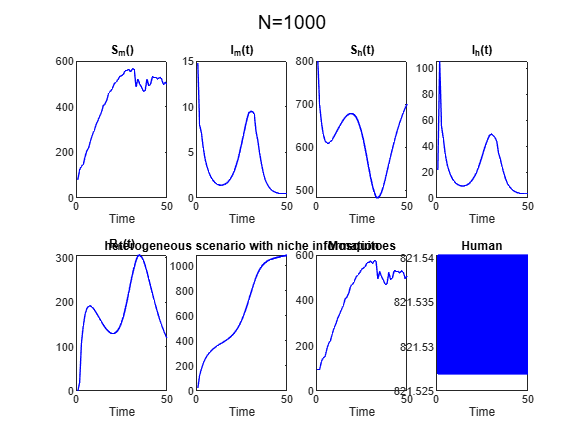

gsua_eval(Mia',TU,xdata1);

TU.Properties.CustomProperties.output=1:8;